boat.L = 0.2;         % length in meters
boat.W = 0.2;         % width in meters
boat.HB = boat.W / 2;  % half breadth in meters
boat.D = 0.2;         % depth in meters

%boat.mass = 18;       % kg
boat.n = 2;         % shape parameter (dimensionless)
boat.density = 500; %kg/m^3

water_density = 1000; %kg/m^3
colormap;
clear mesh;

mesh.dy = 0.001;
mesh.dz = 0.001;
mesh.dx = 0.001;
mesh.ys = -boat.HB:mesh.dy:boat.HB;
mesh.zs = 0:mesh.dz:boat.D;
mesh.xs = -boat.L/2:mesh.dx:boat.L/2;
[mesh.xgrid, mesh.ygrid,mesh.zgrid] = meshgrid(mesh.xs, mesh.ys, mesh.zs);
[mesh.xgrid, mesh.ygrid] = meshgrid(mesh.xs, mesh.ys);

hull3D = squareHull(mesh,boat);
boat.num_cells = sum(hull3D(:));
boat.mass = boat.num_cells*boat.density*mesh.dx*mesh.dy*mesh.dz;
boat.mass_per_cell = boat.mass/boat.num_cells;
boiyant = boat.mass*9.81;

theta = 45;

masses3D = hull3D*boat.mass_per_cell;
boat.COM = centerOfMass3D(masses3D, mesh)

boat = struct with fields:
                L: 0.2000
                W: 0.2000
               HB: 0.1000
                D: 0.2000
                n: 2
          density: 500
        num_cells: 8080200
             mass: 4.0401
    mass_per_cell: 5.0000e-07
              COM: [-4.2874e-18 -1.0589e-18 0.1005]


fun = @(d) massDiff3D(mesh, boat, theta, d);
d0 = boat.D/2;
d = fzero(fun, d0);
water = computeWater3D(d, theta, mesh);
sub_region = hull3D & water;
COB = centerOfMass3D(sub_region, mesh);
force = [0, -boiyant*sind(theta), boiyant*cosd(theta)]

force =          0  -28.0250   28.0250


r = COB - boat.COM

r =     0.0000    0.0325   -0.0322


moment = cross(r, force)

moment =     0.0073   -0.0000   -0.0000


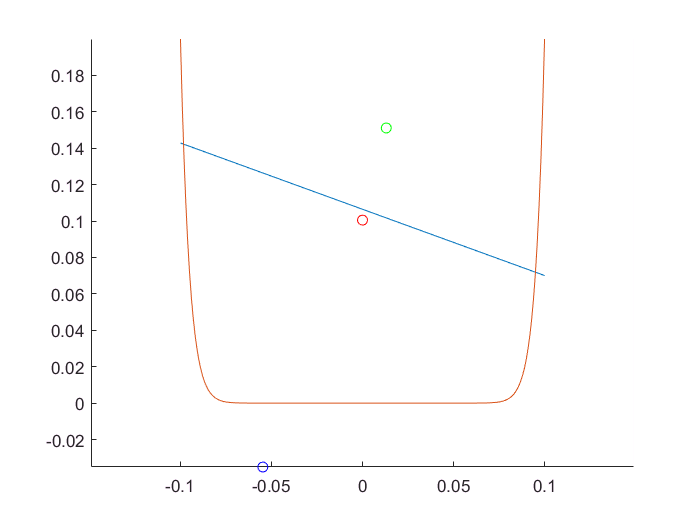

Y = -0.1:0.001:0.1;
station = (((2.*Y)./boat.W).^20).*boat.D;
waterline = tand(theta).*Y + d;
figure;
hold on;
plot(force(2)/(200) + COB(2), force(3)/(200) + COB(3), 'bo');
plot(COB(2), COB(3), 'go');
plot(boat.COM(2), boat.COM(3), 'ro');
plot(Y,waterline);
plot(Y,station);
xlim([-0.1,0.1]);
axis('equal');
hold off;

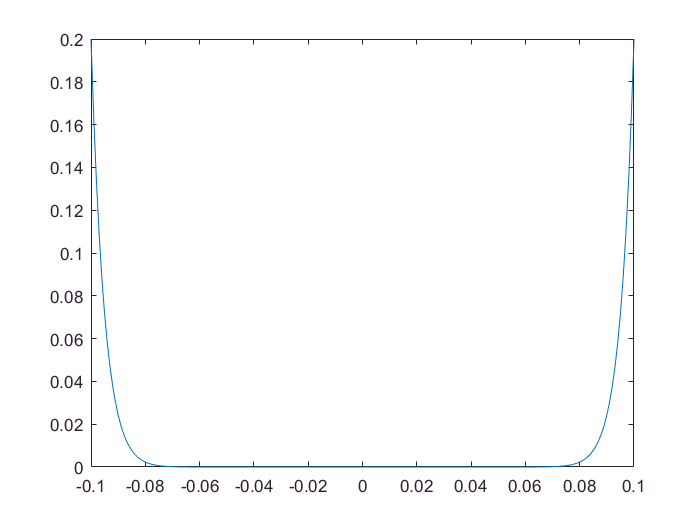


hull3D = squareHull(mesh,boat);
boat.num_cells = sum(hull3D(:));
boat.mass = boat.num_cells*boat.density*mesh.dx*mesh.dy*mesh.dz;
boat.mass_per_cell = boat.mass/boat.num_cells;

masses3D = hull3D*boat.mass_per_cell;

boat.COM = centerOfMass3D(masses3D, mesh);
plot(Y,station);

torques = [];
figure;
hold on;
plot(boat.COM(2), boat.COM(3), 'ro');
for theta = 0:5:160
    clear r
    fun = @(d) massDiff3D(mesh, boat, theta, d);
    d0 = boat.D/2;
    d = fzero(fun, d0);
    water = computeWater3D(d, theta, mesh);
    sub_region = hull3D & water;
    COB = centerOfMass3D(sub_region, mesh); %find COB
    plot(COB(2), COB(3), 'go');
    
    r = COB - boat.COM;
    boiyant = boat.mass*9.81;
    force = [0, -boiyant*sind(theta), boiyant*cosd(theta)];
    moment = cross(r,force);
    
   
   
    torques = [torques; moment];
  
end

Exiting fzero: aborting search for an interval containing a sign change
    because no sign change is detected during search.
Function may not have a root.


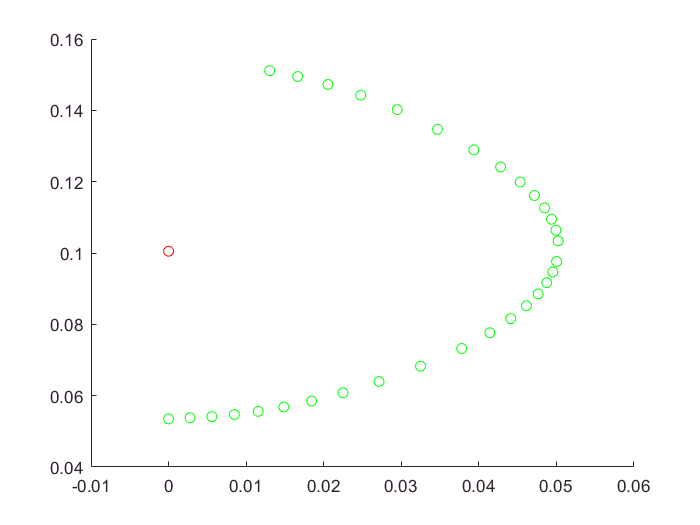

hold off;

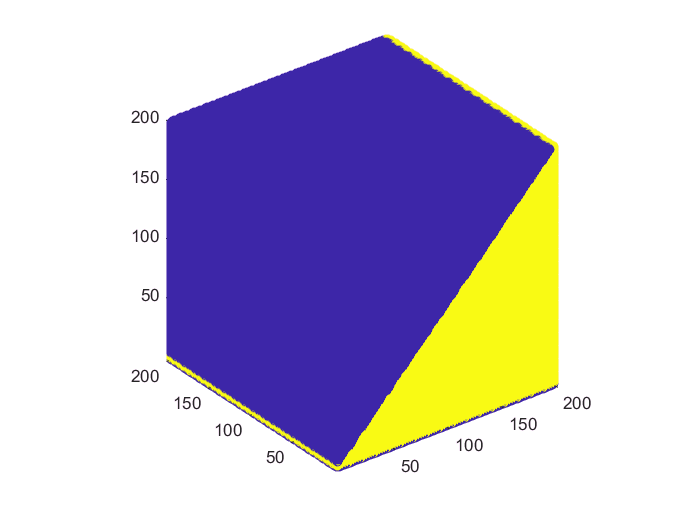

[X,Y,Z] = ndgrid(1:size(sub_region,1), 1:size(sub_region,2), 1:size(sub_region,3));
pointsize = 30;
scatter3(X(:), Y(:), Z(:), pointsize, sub_region(:));
axis('equal');

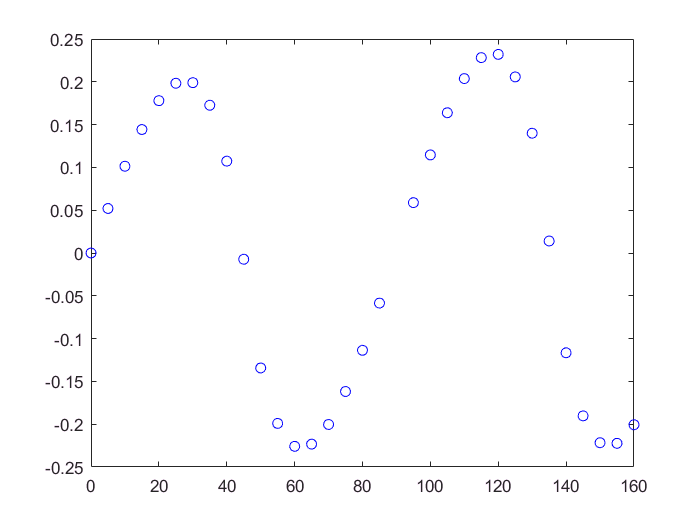

figure;
thetas = 0:5:160;
plot(thetas,torques(:,1), 'bo');

torques(:,1)

ans =     0.0000
    0.0520
    0.1014
    0.1443
    0.1780
    0.1983
    0.1990
    0.1726
    0.1073
   -0.0073


function COM = centerOfMass3D(masses, mesh)
    M = sum(masses(:));
    x_masses = masses.*mesh.xgrid;
    x_COM = sum(x_masses(:))/M;
    y_masses = masses.*mesh.ygrid;
    y_COM = sum(y_masses(:))/M;
    
    z_masses = masses.*mesh.zgrid;
    z_COM = sum(z_masses(:))/M;
    COM = [x_COM,y_COM, z_COM];
end




function water = computeWater3D(d,theta,mesh)
    % water: compute the level of the water
    % d: depth of waterline in meters
    % theta: angle of waterline in degrees
    % mesh: structure containing ys and zgrid
    % returns: logical matrix
    
    y = mesh.ygrid;
    
    z = tand(theta) .* y + d;
    if theta <= 90
        water = mesh.zgrid <z;
    end
    if theta > 90
        water = mesh.zgrid > z;
    end
end


function hull = computeHull3D(mesh, boat)
    %computes a 3D hull with breadth B, depth D, and 
    %length L
    B = boat.W;
    D = boat.D;
    L = boat.L;
    center_station = (((2.*mesh.ygrid)./B).^20).*D;
    profile = (((2.*mesh.xgrid)./L).^20).*D;
    z = center_station + profile;
    hull = mesh.zgrid  >z;
end



function diff = massDiff3D(mesh,boat,theta,d)
    
%     for a value of theta and d, finds the differnce 
%     in boiyant and weight forces
    
    hull3D = computeHull3D(mesh, boat);
    boat.num_cells = sum(hull3D(:));
    boat.mass = boat.num_cells*mesh.dy*mesh.dz*mesh.dx*boat.density;
    water = computeWater3D(d, theta, mesh);
    sub_region = hull3D & water;
    
    displaced_water = sum(sub_region(:))*mesh.dx*mesh.dy*mesh.dz*1000;
    
    diff = boat.mass - displaced_water;
end

function hull = squareHull(mesh, boat)
    %computes a 3D hull with breadth B, depth D, and 
    %length L
    z = 0;
    hull = mesh.zgrid  > z;
end

